# **スポーツ統計学演習 Week 2**

## 統計量の分布：　t 分布


$$x\sim N\left(\mu ,\sigma^2 \right)$$



$$t=\frac{\bar{\;x} -\mu \;}{s/\sqrt{\;n}}$$


% 1つの標本から t 値を計算

% 母集団　（正規分布）
mu = 3 ;
sigma = 2 ;

% 標本/サンプル
n = 10 ; % サンプルサイズ
x = mu + randn(n,1)*sigma ;


% サンプル平均・不偏分散・不偏標準偏差
m = sum(x) / n 

m = 3.6737

v = sum((x-m).^2) / (n-1)

v = 5.9989

s = vv^0.5

s = 2.0623


% MATLAB関数を用いて計算
m = mean(x) ;
s = std(x) ;

%　t 値を計算
t = (m - mu) / (s/sqrt(n))

t = 0.8699


% MATLAB関数を用いて計算 (statistics & machine learning toolbox)
[h,p,ci,stats] = ttest(x, mu) ;
t = stats.tstat

t = 0.8699

% t 分布のシミュレーション

% 母集団　（正規分布）の平均値・標準偏差、サンプルサイズ
mu = 3 ;
sigma = 2 ;
n = 10 ; % サンプルサイズ

% 標本のシミュレーション
nSim = 10000 ;
xx = mu + randn(n,nSim)*sigma ;

% サンプル平均・不偏標準偏差
mm = mean(xx) ;
ss = std(xx) ;

%　t 値を計算
tt = (mm - mu) ./ (ss/sqrt(n))

tt =     0.0971    0.0933   -2.1246    1.2516   -0.6874    3.1348   -1.7390   -0.8020   -0.1053   -0.2688   -0.1984   -1.5256    0.8891    0.1794   -0.3333   -0.4099    2.4921    1.2728    0.2322   -1.7108    0.3413    0.6379    1.1463   -1.2080    0.2821   -1.0351   -1.2995    0.0579   -0.7360   -0.3613    1.8386    0.5632    2.1297   -1.7383    1.1017    0.0113    1.4634    0.0193    0.4326    0.7984   -0.0584   -1.0876   -0.3161   -2.1538    0.3318   -1.0228    1.0806    1.1350    0.3306    0.6478


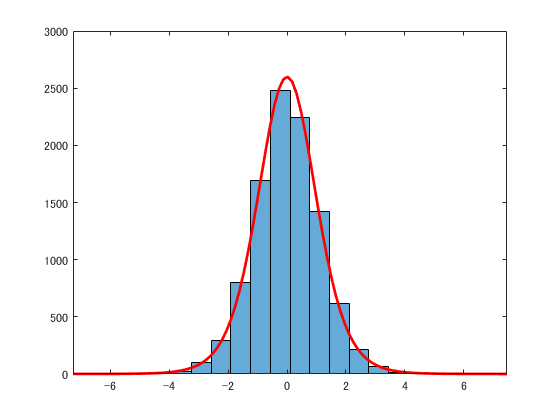


% ヒストグラム
nBin = 20 ;
h = histogram(tt, nBin) ; hold on

% t 分布を重ね書き
df = n-1 ;
xLim = get(gca, 'xlim') ;
xxx = linspace(xLim(1), xLim(2), 100) ;
y = tpdf(xxx, df) * (nSim*h.BinWidth) ;
plot(xxx, y, 'r', 'linewidth', 2)

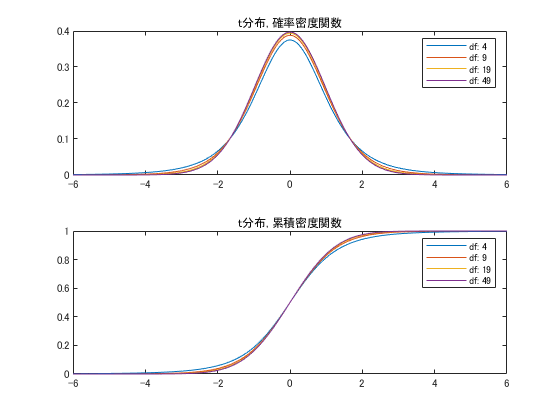

関数または変数 'yline' が未定義です。

% 異なる自由度の t 分布のシミュレーション

nArray = [5, 10, 20, 50] ;

xxx = -6:0.01:6 ;
for k = 1:length(nArray)
    df = nArray(k) - 1  ;
    
    figure(2)
    ax1 = subplot(2,1,1) ;
    y1 = tpdf(xxx, df) ;
    plot(xxx, y1) ; hold on
    
    ax2 = subplot(2,1,2) ;
    y2 = tcdf(xxx, df) ;
    plot(xxx, y2) ; hold on
    
    % 凡例テキスト
    txt{k} = sprintf('df: %d', df) ;
end

% 凡例、タイトル
axes(ax1) ;
legend(txt)
title('t分布, 確率密度関数')

axes(ax2) ;
legend(txt)
title('t分布, 累積密度関数')